** #Indoor Channel Modeling: 1–10 GHz Ray-Tracing and Beamforming Simulation**

**This script implements a physics-informed framework for modeling indoor wireless propagation in the 1–10 GHz range. It includes multilayer wall reflection calibration, 2D ray-tracing with diffraction, frequency-dependent coverage analysis, power-delay profiling, path-loss fitting, and phased-array beamforming simulation. The results support system-level evaluation of indoor channel characteristics such as signal coverage, temporal dispersion, and beamforming gain.**

**For a detailed explanation of the theory, assumptions, and analysis, please refer to the accompanying report: **wireless_course_report.pdf**.**

**Module 1: Global Parameters & Multilayer Calibration**

This section defines physical and dielectric parameters and computes the frequency-dependent reflection coefficient of a three-layer wall using transfer-matrix theory.

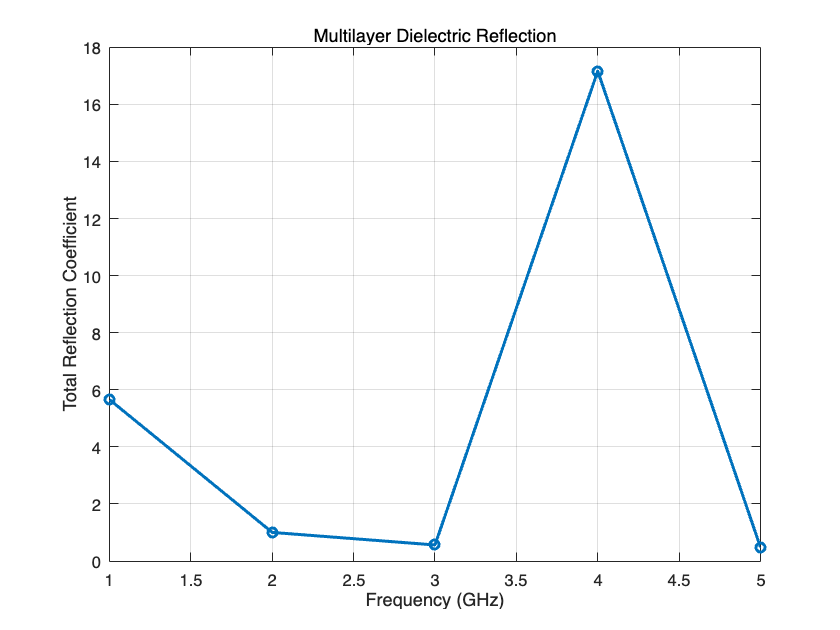

%% Module 1: Global Parameters & Multilayer Calibration
clear; close all; clc;

% Define fundamental constants: speed of light, permeability and permittivity of free space
c0   = 2.99792458e8; 
u0 = 4*pi*1e-7; 
eps0 = 1/(u0*c0^2);

% Define material parameters for a three-layer wall: relative permittivity, conductivity, and thickness
layers = struct('eps_r',{3,9,81}, 'sigma',{0.02,0,0.02}, 'd',{0.01,0.005,0.02});

% Frequency sweep setup from 1 GHz to 5 GHz
nfreq = 5; 
frequencies = linspace(1e9,5e9,nfreq);

% Preallocate vector for total reflection coefficients across frequencies
R_total = zeros(1,nfreq);

%Loop over frequencies to calculate reflection coefficient using transfer matrix method
for k = 1:nfreq
    f     = frequencies(k); 
    omega = 2*pi*f; 
    k0    = omega/c0;             % Free-space wave number
    M     = eye(2);               % Initialize transfer matrix

    for idx = 1:numel(layers)
        er   = layers(idx).eps_r; 
        sig  = layers(idx).sigma; 
        d    = layers(idx).d;

        % Compute complex refractive index and phase shift through each layer
        neff = sqrt(er - 1j*sig/(omega*eps0)); 
        phi  = k0*neff*d;

        % Build transfer matrix for current layer and accumulate
        T    = [cos(phi), 1j*sin(phi)/neff; 
                1j*neff*sin(phi), cos(phi)];
        M    = M * T;
    end

    % Compute overall reflection coefficient magnitude
    R_total(k) = abs(M(2,1)/M(1,1));
end

% Plot the reflection coefficient versus frequency
figure;
plot(frequencies/1e9, R_total, '-o', 'LineWidth', 2);
xlabel('Frequency (GHz)'); 
ylabel('Total Reflection Coefficient');
title('Multilayer Dielectric Reflection'); 
grid on;

**Module 2: 2D Ray-Tracing + Knife-Edge Diffraction**

This section simulates the total field distribution by combining the direct wave, up to second-order reflected waves via image sources, and edge-diffracted components using knife-edge diffraction theory.

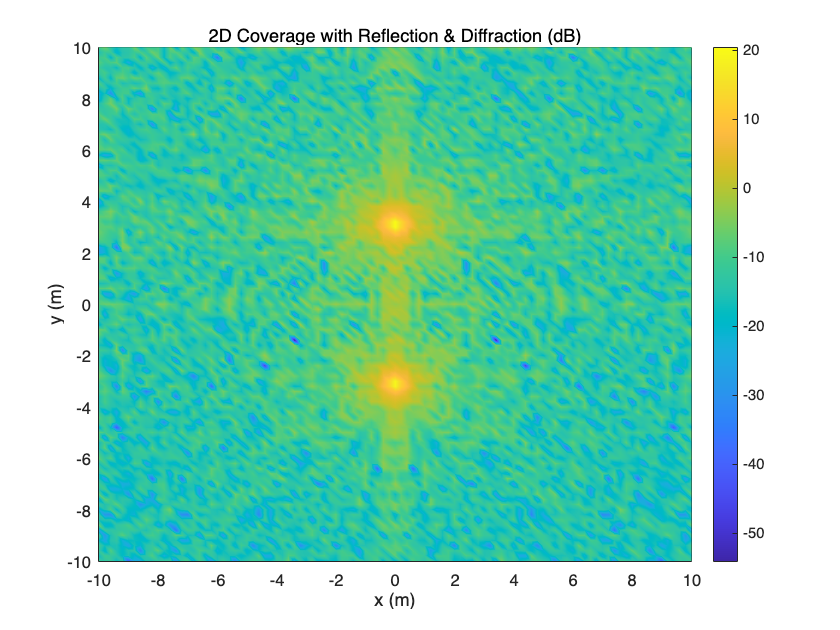

%% Module 2: 2D Ray-Tracing + Knife-Edge Diffraction
p_src = [0,3.1];
wall  = [ -10,0,10,0;  -10,10,10,10;  -10,0,-10,10;  10,0,10,10 ];
x_range = -10:0.2:10; y_range = -10:0.2:10;
[xm, ym] = meshgrid(x_range, y_range);
mididx = round(nfreq/2);
f0     = frequencies(mididx); k0 = 2*pi*f0/c0;

% Image sources for reflections
images = struct('pos',{},'R',{});
for order = 1:2
    for w = 1:size(wall,1)
        p1     = wall(w,1:2); p2 = wall(w,3:4);
        normal = ([p1(2)-p2(2), p2(1)-p1(1)]); normal = normal/norm(normal);
        d_src  = dot(p_src-p1, normal);
        imgPos = p_src - 2*d_src * normal;
        images(end+1).pos = imgPos;
        images(end).R     = R_total(mididx)^order;
    end
end

% Direct + reflected field
r0   = sqrt((xm-p_src(1)).^2 + (ym-p_src(2)).^2);
E0   = (1./r0) .* exp(-1j*k0.*r0);
Ert  = zeros(size(E0));
for m = 1:numel(images)
    dmat = sqrt((xm-images(m).pos(1)).^2 + (ym-images(m).pos(2)).^2);
    Ert  = Ert + images(m).R .* (1./dmat) .* exp(-1j*k0.*dmat);
end

% Knife-edge diffraction field
E_diff = zeros(size(E0));
lambda = c0 / f0;
h      = 1.5;  % edge height
for w = 1:size(wall,1)
    ends = [wall(w,1:2); wall(w,3:4)];
    for ke = 1:2
        edge = ends(ke,:);
        d1   = sqrt((p_src(1)-edge(1))^2 + (p_src(2)-edge(2))^2);
        d2   = sqrt((xm-edge(1)).^2 + (ym-edge(2)).^2);
        nu   = -h * sqrt(2/lambda * (1./d1 + 1./d2));
        C    = fresnelc(nu);    % cosine Fresnel integral
        S    = fresnels(nu);    % sine Fresnel integral
        F    = 0.5*(1 - C - 1j*(1 - S));
        D    = F .* exp(-1j*pi/4);
        E_diff = E_diff + D .* (1./(d1+d2)) .* exp(-1j*k0*(d1+d2));
    end
end

% Total field = direct + reflected + diffracted
E_total = E0 + Ert + E_diff;

figure;
pcolor(x_range, y_range, 20*log10(abs(E_total)));
shading interp; colorbar;
title('2D Coverage with Reflection & Diffraction (dB)');
xlabel('x (m)'); ylabel('y (m)');

**Module 3: Frequency Sweep Coverage**

This section evaluates how signal coverage changes across different frequencies (1, 3, 5, and 10 GHz), revealing frequency-selective effects and spatial interference patterns.

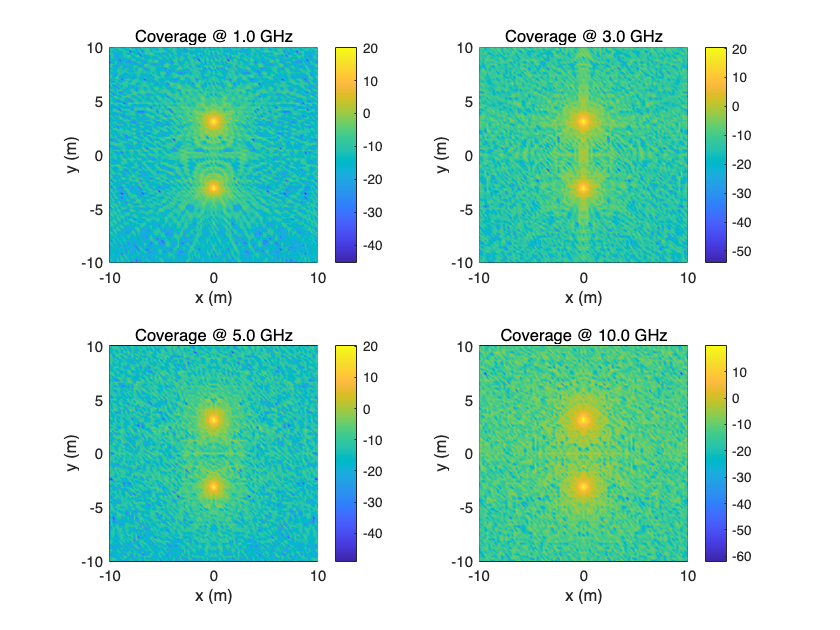

%% Module 3: Frequency Sweep Coverage
f_sweep = [1e9,3e9,5e9,10e9];
figure(3);
for i = 1:4
    fi     = f_sweep(i); ki = 2*pi*fi/c0;
    r0_i   = sqrt((xm-p_src(1)).^2 + (ym-p_src(2)).^2);
    Ei     = (1./r0_i) .* exp(-1j*ki.*r0_i);
    Ert_i  = zeros(size(Ei));
    for m = 1:numel(images)
        dmat  = sqrt((xm-images(m).pos(1)).^2 + (ym-images(m).pos(2)).^2);
        Ert_i = Ert_i + images(m).R .* (1./dmat) .* exp(-1j*ki.*dmat);
    end
    E_diff_i = zeros(size(Ei));
    lambda_i = c0 / fi;
    for w = 1:size(wall,1)
        ends = [wall(w,1:2); wall(w,3:4)];
        for ke = 1:2
            edge = ends(ke,:);
            d1   = sqrt((p_src(1)-edge(1))^2 + (p_src(2)-edge(2))^2);
            d2   = sqrt((xm-edge(1)).^2 + (ym-edge(2)).^2);
            nu   = -h * sqrt(2/lambda_i * (1./d1 + 1./d2));
            C    = fresnelc(nu);
            S    = fresnels(nu);
            F    = 0.5*(1 - C - 1j*(1 - S));
            D    = F .* exp(-1j*pi/4);
            E_diff_i = E_diff_i + D .* (1./(d1+d2)) .* exp(-1j*ki*(d1+d2));
        end
    end
    E_tot_i = Ei + Ert_i + E_diff_i;
    subplot(2,2,i);
    pcolor(x_range, y_range, 20*log10(abs(E_tot_i)));
    shading interp; colorbar;
    title(sprintf('Coverage @ %.1f GHz', fi/1e9));
    xlabel('x (m)'); ylabel('y (m)');
end

**Module 4: Power-Delay Profile & RMS Delay Spread**

This section constructs the power-delay profile (PDP) based on simulated multipath components and calculates the RMS delay spread and coherence bandwidth, which reflect the channel's temporal dispersion.

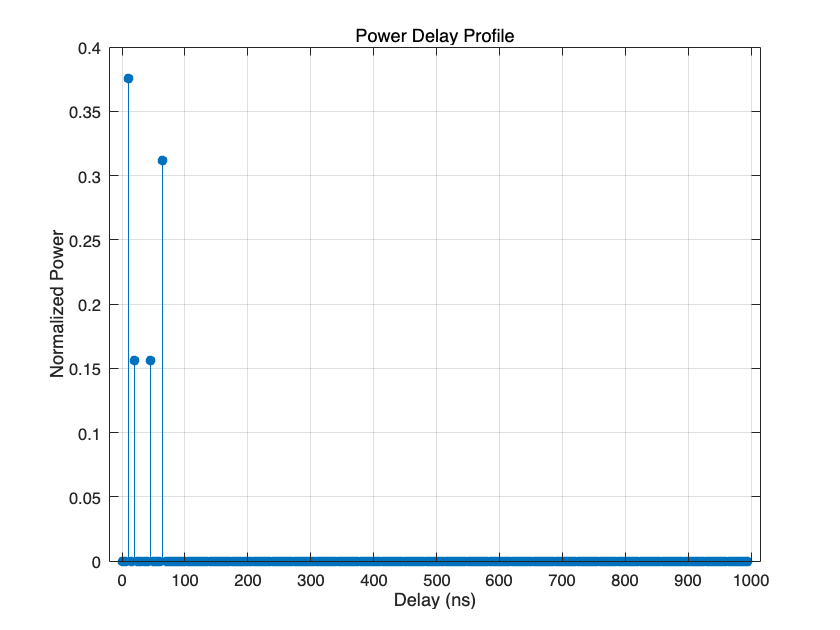

%% Module 4: Power-Delay Profile & RMS Delay Spread
paths(1) = struct('tau', norm(p_src)/c0, 'amp', 1);
for m = 1:numel(images)
    paths(m+1).tau = norm(p_src - images(m).pos)/c0;
    paths(m+1).amp = images(m).R;
end
Ntaps = 200; Ts = 5e-9; PDV = zeros(1, Ntaps);
for m = 1:numel(paths)
    idx = round(paths(m).tau/Ts) + 1;
    if idx <= Ntaps
        PDV(idx) = PDV(idx) + abs(paths(m).amp)^2;
    end
end
PDP = PDV / sum(PDV); tau = (0:Ntaps-1)*Ts;
figure; stem(tau*1e9, PDP, 'filled'); grid on;
title('Power Delay Profile'); xlabel('Delay (ns)'); ylabel('Normalized Power');

mu1     = sum(tau .* PDP);
mu2     = sum((tau.^2) .* PDP);
tau_rms = sqrt(mu2 - mu1^2); Bc = 1/(5*tau_rms);
disp(['RMS delay spread=', num2str(tau_rms*1e9), ' ns, Bc=', num2str(Bc/1e6), ' MHz']);

RMS delay spread=23.7871 ns, Bc=8.4079 MHz


**Module 5: Path-Loss Exponent Fitting**

This section calculates distance-based path loss over the 2D grid and fits a log-distance path loss model to extract the empirical path-loss exponent n.

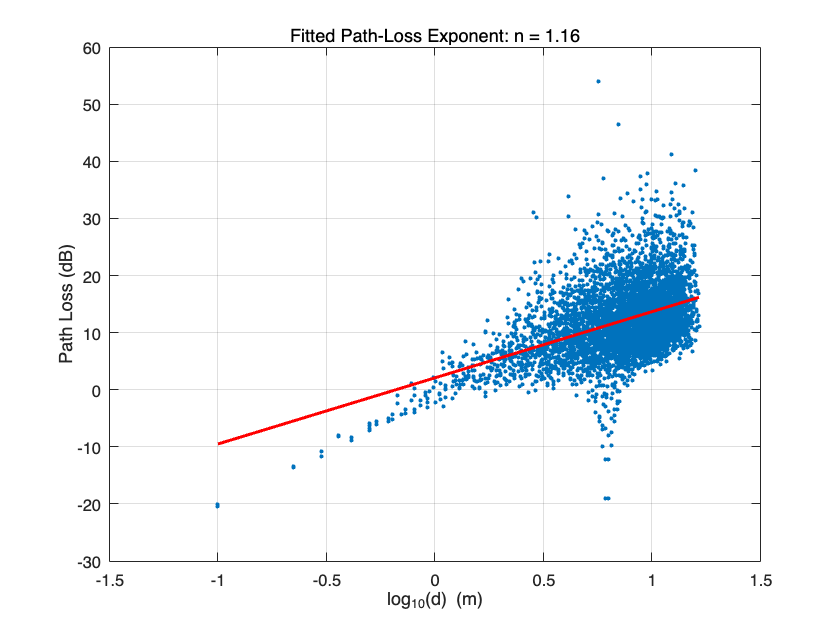

% Module 5: Path-Loss Exponent Fitting
d    = sqrt((xm(:)-p_src(1)).^2 + (ym(:)-p_src(2)).^2);
pldb = -20 * log10(abs(E_total(:)));
p    = polyfit(log10(d), pldb, 1);
n    = p(1) / 10;
figure;
plot(log10(d), pldb, '.', 'MarkerSize', 8); hold on;
plot(log10(d), polyval(p, log10(d)), 'r-', 'LineWidth', 2);
grid on; xlabel('log_{10}(d) (m)'); ylabel('Path Loss (dB)');
title(sprintf('Fitted Path-Loss Exponent: n = %.2f', n));

**Module 6: Single-Antenna Coverage Metrics**

This section generates a heatmap of path loss and a map of direct-path time-of-flight (ToF), which are useful for assessing coverage reliability and positioning accuracy.

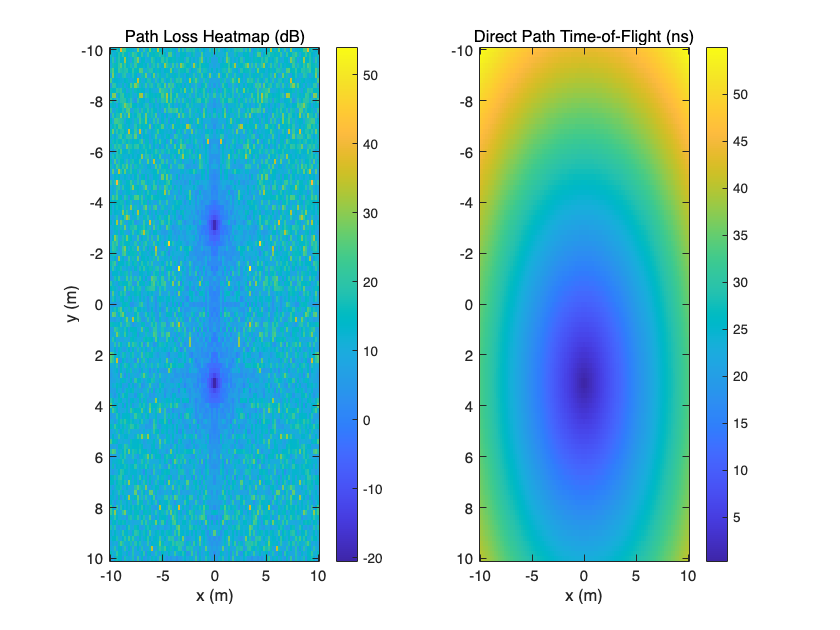

%% Module 6: Single-Antenna Coverage Metrics
PLmap = -20*log10(abs(E_total));
TOF   = r0/c0*1e9;
figure;
subplot(1,2,1); imagesc(x_range, y_range, PLmap); colorbar;
title('Path Loss Heatmap (dB)'); xlabel('x (m)'); ylabel('y (m)');
subplot(1,2,2); imagesc(x_range, y_range, TOF); colorbar;
title('Direct Path Time-of-Flight (ns)'); xlabel('x (m)');

**Module 7: Phased-Array Beamforming**

This section simulates a 16-element uniform linear array (ULA) and applies beamforming weights to steer the main beam toward a target angle, evaluating directional gain and array performance.

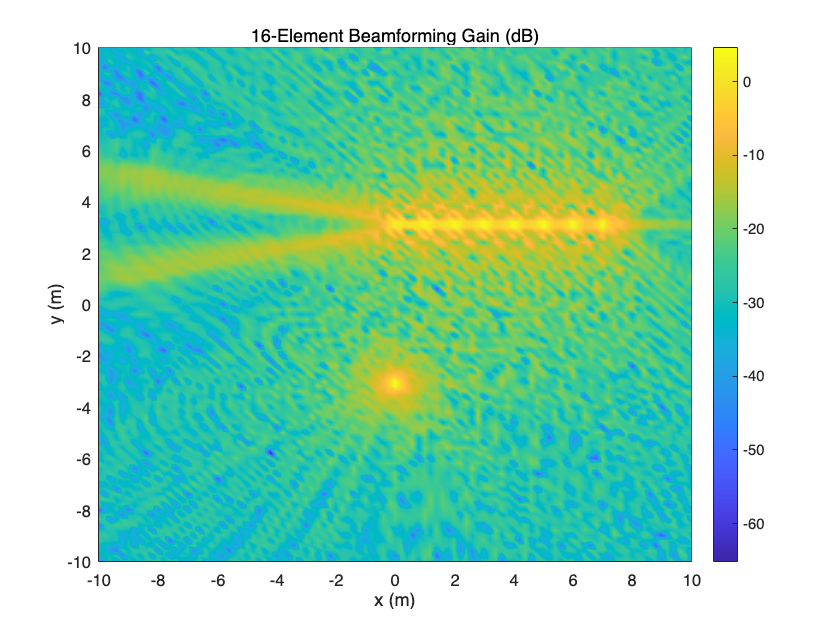

%% Module 7: Phased-Array Beamforming
N      = 16;           % Number of elements in the ULA
d_tx   = 0.5;          % Inter-element spacing in wavelengths
theta0 = 30;           % Steering angle in degrees
w      = exp(-1j*(0:N-1)*k0*d_tx*sin(theta0));  % Beamforming weights
E_sum  = zeros(size(xm));                      % Initialize total field with beamforming

for n = 1:N
    src_pt = p_src + [(n-1)*d_tx, 0];          % Position of each element
    r_n    = sqrt((xm-src_pt(1)).^2 + (ym-src_pt(2)).^2);
    En     = (1./r_n).*exp(-1j*k0.*r_n);       % Direct field from element
    for m = 1:numel(images)
        dmat = sqrt((xm-images(m).pos(1)).^2 + (ym-images(m).pos(2)).^2);
        En   = En + images(m).R.*(1./dmat).*exp(-1j*k0.*dmat);  % Add reflected fields
    end
    E_sum = E_sum + w(n).*En;                 % Weighted sum across array elements
end

SISOmax = max(abs(En).^2, [], 'all');          % Max single antenna power for normalization
BFgain  = 10 * log10(abs(E_sum).^2 / SISOmax); % Beamforming gain in dB

figure; 
pcolor(x_range, y_range, BFgain); shading interp; colorbar;
title('16-Element Beamforming Gain (dB)'); xlabel('x (m)'); ylabel('y (m)');

**Module 8: 3D Ray Visualization + Beam Gain Overlay**

This final section creates a 3D visualization of the indoor scene, including walls, ray paths from reflections and diffractions, and an overlaid beamforming gain surface for spatial interpretation.

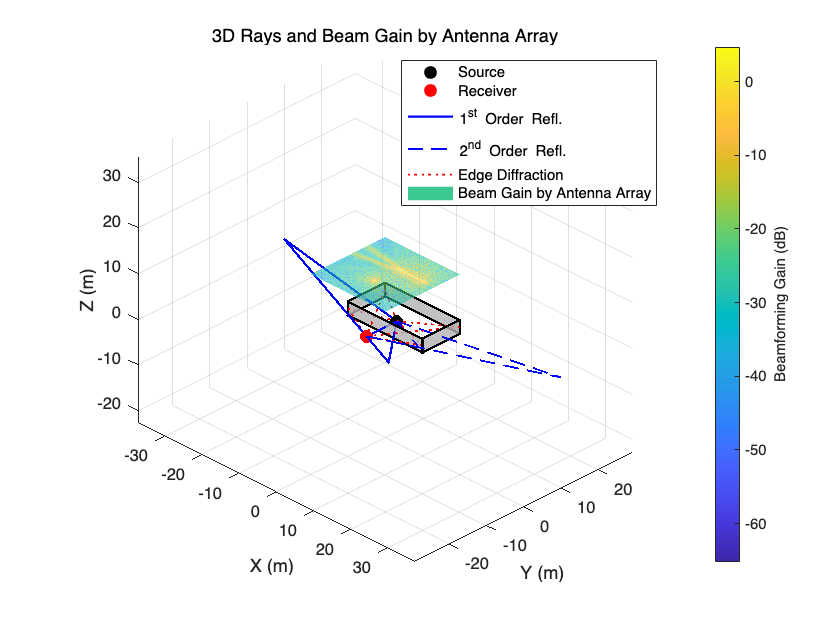

%% Module 8: 3D Ray Visualization + Beam Gain Overlay
figure; clf; hold on; axis equal; grid on;
wall_height = 3;
for w = 1:size(wall,1)
    p1 = [wall(w,1:2), 0]; p2 = [wall(w,3:4), 0];
    p3 = p2 + [0,0,wall_height]; p4 = p1 + [0,0,wall_height];
    patch('Vertices',[p1; p2; p3; p4], 'Faces',[1 2 3 4], ...
          'FaceColor',[0.7 0.7 0.7], 'FaceAlpha',0.8, ...
          'EdgeColor','k','LineWidth',1.5);
end

p_src3 = [p_src,1.5]; rec_pt3 = [0,-5,1.5];  % Define 3D source and receiver points
hSrc = plot3(p_src3(1),p_src3(2),p_src3(3),'ko','MarkerFaceColor','k','MarkerSize',8);
hRec = plot3(rec_pt3(1),rec_pt3(2),rec_pt3(3),'ro','MarkerFaceColor','r','MarkerSize',8);
hRef1=[]; hRef2=[]; hDiff=[];

% Plot reflected ray paths (1st and 2nd order)
for m = 1:numel(images)
    widx = ceil(m/2); p1 = wall(widx,1:2);
    normal = ([p1(2)-wall(widx,4),wall(widx,3)-p1(1)]); normal = normal/norm(normal);
    img2d  = images(m).pos;
    t      = dot((p1-img2d),normal)/dot((rec_pt3(1:2)-img2d),normal);
    P_ref  = [img2d + t*(rec_pt3(1:2)-img2d),1.5];
    rayPts = [p_src3;P_ref;rec_pt3];
    if mod(m,2)==1
        h = plot3(rayPts(:,1),rayPts(:,2),rayPts(:,3),'-b','LineWidth',1.5);
        if isempty(hRef1), hRef1=h; end
    else
        h = plot3(rayPts(:,1),rayPts(:,2),rayPts(:,3),'--b','LineWidth',1.2);
        if isempty(hRef2), hRef2=h; end
    end
end

% Plot diffraction ray paths from wall edges
for w = 1:size(wall,1)
    ends2d = [wall(w,1:2);wall(w,3:4)];
    for k = 1:2
        P_edge3 = [ends2d(k,:),1.5];
        h1 = plot3([p_src3(1),P_edge3(1)],[p_src3(2),P_edge3(2)],[p_src3(3),P_edge3(3)],':r','LineWidth',1.2);
        h2 = plot3([P_edge3(1),rec_pt3(1)],[P_edge3(2),rec_pt3(2)],[P_edge3(3),rec_pt3(3)],':r','LineWidth',1.2);
        if isempty(hDiff), hDiff=h1; end
    end
end

% Overlay beamforming gain on a horizontal surface
zOffset = wall_height + 10;
hSurf = surf(xm, ym, zOffset*ones(size(xm)), BFgain, 'FaceAlpha',0.6,'EdgeColor','none');
colormap parula; hcb = colorbar; ylabel(hcb,'Beamforming Gain (dB)');
legend([hSrc,hRec,hRef1,hRef2,hDiff,hSurf], ...
       {'Source','Receiver','1^{st} Order Refl.','2^{nd} Order Refl.', ...
        'Edge Diffraction','Beam Gain by Antenna Array'}, 'Location','best');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('3D Rays and Beam Gain by Antenna Array'); view(45,30);